# Saltwater Intrusion

## Introduction 

Saltwater intrusion is when seawater infiltrates freshwater sources. It is important to track saltwater intrusion of aquifers because groundwater is a critical source of drinking water for many people in the United States. As sea levels rise, freshwater coastal aquifers will be more threatened by saltwater intrusion, putting populations and communities that depend on coastal aquifers at risk of losing their freshwater drinking source. Additionally, coastal agriculture is impacted by saltwater intrusion, where salt deposits interact with soil chemistry and can be harmful to plants (USDA, 2019 & USGS, n.d.) The rate at which aquifers are being affected varies, so having a model to accurately predict salt water intrusion can help determine which areas need more immediate action for prevention and mitigation strategies (Barlow & Reichard, 2010). The main theme of this research paper is developing a model for salt water intrusion based on previous work by Mark Bakker. Understanding the dynamics of saltwater intrusion is a pressing issue with dedicated annual/biannual meetings to share new developments at the Salt Water Intrusion Meeting.

While our model was not based on a specific geographical location where saltwater intrusion occurs, other studies were conducted as case studies in set geographical locations and used more dimensions to create a more accurate model (Bouzouf et al., n.d.). Other models have also used similar assumptions to Bakker, but compared more accurate methods such as the partial Newton and partial Picard methods (Putti & Paniconi, 1995). Additionally, more robust models have been developed, such as the Sea Water Intrusion (SWI2) package for MODFLOW, a model used by the United States Geological Survey (Bakker et al., 2013).

## **Equations**

**Fundamental physical processes**

Saltwater intrusion is when seawater comes into contact with freshwater sources. This occurs most often through sea level rise when higher tides begin impacting areas of low elevation and when seawater infiltrates freshwater aquifers (USDA, 2019 & USGS, n.d.) Excess pumping of groundwater in coastal areas can also promote saltwater intrusion into aquifers (USGS, n.d.). This model aims to simulate the intrusion of saltwater into a freshwater aquifer under set initial conditions.

**Relevant equations**

Equation 1 is the differentiated discharge vector, which was obtained from the vertically integrated flux (discharge) vector under the Boussinesq approximation.

Equation 2 is the differentiation of the salt discharge vector, obtained from the vertically integrated flux vector in the saltwater zone (salt discharge).

Assuming a steady state given equation 3.

the Ghyben-Herzberg condition (equation 4) is used to calculate h.

Glover’s formula was applied to determine boundary conditions.  

clear 
clc

**Describe all terms and parameters:**

All terms and parameters are listed below. No value was given for infiltration of freshwater (N), so its value was assumed. 

k = 2; % hydraulic conductivity [m/day]
porosity = 0.2; % effective porosity (defined as n in the paper)
S = 1; % storage coefficient
H = 45; % thickness of aquifer [m]
zb = -45; % bottom of aquifer [m]
zt = 0; % top of aquifer [m]
L = 1000; % length of cross section [m]
W = 1; % width of cross section normal to plane of flow [m]
vs = 0.025; % dimensionless density
T = k*(zt-zb); % transmissivity of freshwater
tau = k*vs*(zt-zb); % transmissivity of saltwater
N = 1; % infiltration of freshwater
Q_0 = 0.1; % uniform flow towards the coast (boundary condition) [m2/day]

stepping variables:

dx  = 10; % space step [m]
xf = L; 
xvec = [0:dx:xf];
dt = 0.4; % time step [days]
tf = 500*365; % final time [days]


**Assumptions**

Based on assumptions by Bakker (Bakker, 2000):

- The resistance to flow in the vertical direction is neglected (Dupuit approximation)

- Mass balance is replaced by volume balance (Boussinesq approximation)

- Density difference between freshwater and saltwater is 2.5%

- Groundwater flow is horizontal

- Freshwater and saltwater are immiscible

## **Numerical Methods**

We use the forward Euler method to solve this coupled system of PDEs. While there are more accurate models to solve these PDEs, forward Euler is most approachable and similar to the block-centered finite difference method used by Bakker.

We obtain the matrix equations used later by discretizing equations 1 and 2, shown below. 

Discretization of equation 1: 

Discretization of equation 2:

The boundary conditions for each simulation were initially defined as follows:

At x = 0, zeta = -2 and h = 0.05. At x = 1000, h = -zeta*vs as defined by equation (4) and zeta = zb, or the bottom of the aquifer.

**Setting up matrices**

m = round(xf/dx + 1); % # of space steps
n = round(tf/dt + 1); % # of time steps

For equation 1:

% template matrix for h
A =  T*dt/(dx^2*S); % diffusivity term
M = speye(m,m);
for i = 1:m
    for j = 1:m
        if i == j
            M(i,j) = 1-2*A;
        elseif i-1== j
            M(i,j) = A;
        elseif i+1 == j
            M(i,j) = A;
        end
    end
    
end 

Boundary conditions for h:

% Dirichlet boundary conditions

M(1,1) = 1;
M(1,2) = 0;
M(m,:) = 0;
M(m,m) = 1;

Foupled portion:

S1 = speye(m,m);
B = tau*dt/(S*dx^2);
for i = 1:m
   for j = 1:m
       if i == j
           S1(i,j) = -2*B;
       elseif i-1==j
           S1(i,j) = B;
       elseif i+1 ==j
           S1(i,j) = B;
        end
    end
end 

Boundary condtions for coupled zeta matrix:

S1(1,1) = 0;
S1(1,2) = 0;
S1(m,:) = 0;
S1(m,m) = 0;

For equation 2:

O = speye(m,m);
C = (tau*dt/(dx^2*porosity));
for i = 1:m
    for j = 1:m
        if i == j
            O(i,j) = 1-2*C;
        elseif i-1==j
            O(i,j) = C;
        elseif i+1 ==j
            O(i,j) = C;
        end
    end  
end 

Boundary conditions for zeta matrix:

% Dirichlet boundary conditions
O(1,1) = 1;
O(1,2) = 0;
O(m,:) = 0;
O(m,m) = 1;

Coupled portion:

S2 = speye(m,m);
D = tau*dt/(vs*dx^2*porosity);
for i = 1:m
   for j = 1:m
       if i == j
           S2(i,j) = -2*D;
       elseif i-1==j
           S2(i,j) = D;
       elseif i+1 ==j
           S2(i,j) = D;
       end
    end   
end 

Boundary conditions for coupled h matrix:

S2(1,1) = 0;
S2(1,2) = 0;
S2(m,:) = 0;
S2(m,m) = 0;

**Solving the matrix problem**

Create empty matrices to store solutions:

h_all = zeros(m,n);
zeta_all = zeros(m,n);

Initial conditions for zeta were determined by using [Web Plot Digitzer](https://apps.automeris.io/wpd/) to extract the initial interface elevation from Figure 1a in Bakker, and plot it using a 3rd order polynomial line of best fit (shown in Figure 1 below).

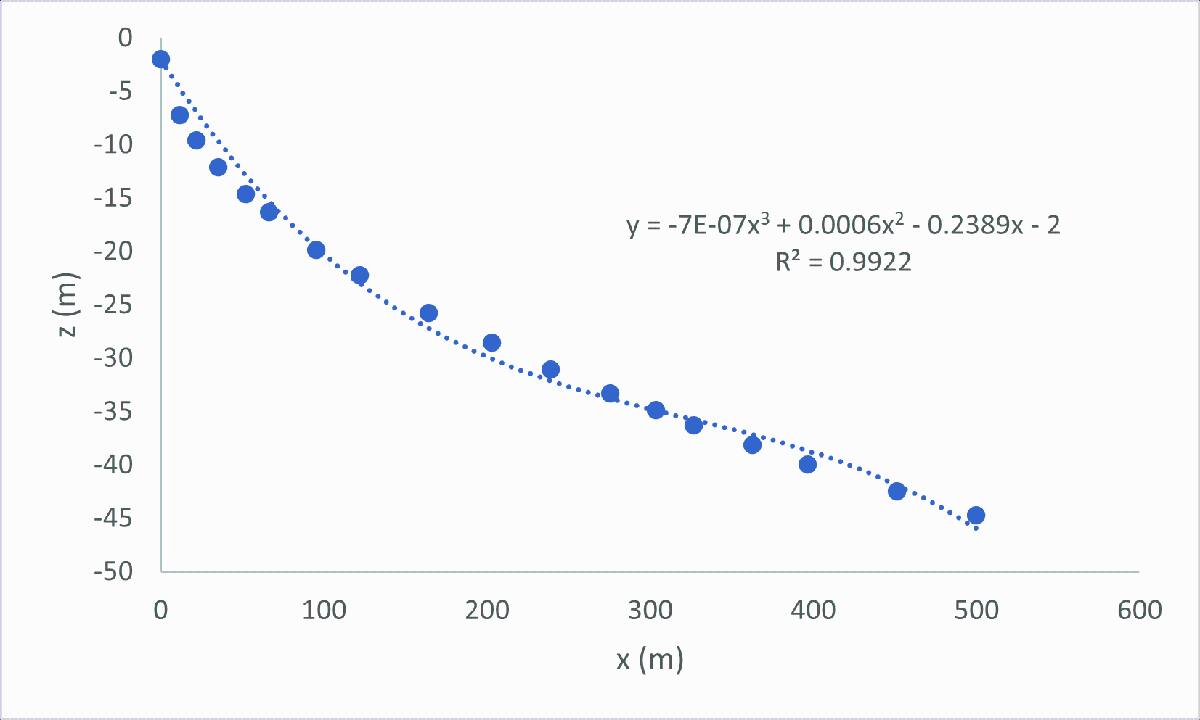

Figure 1. Line of best fit for initial conditions of interface elevation (zeta)

The initial conditions for zeta are determined by the polynomial, with the y intercept (also a boundary condition) is set based on Glover's formula (equation 5).

zeta = -7E-07*xvec.^3 + 0.0006*xvec.^2 - 0.2389*xvec - Q_0/(k*vs); 

zeta(40:end) = zb; % where the interface meets the bottom of the aquifer, it cannot go any deeper
zeta = zeta';
zeta_all(:,1) = zeta;

Initial conditions for h: 

h = zeta*vs; % equation 4: Ghyben-Herzberg
h_all(:,1) = h;


Solve the coupled PDEs:

for t = 2:n
    hnew = M*h + S1*zeta + (N.*dt./S);
    h_all(:,t) = hnew;

    zetanew = O*zeta + S2*h;
    zeta_all(:, t) = zetanew;

    h=hnew;

    zeta = zetanew;
  
end

figure (1)
plot(xvec, zeta_all(:, 1), xvec, zeta_all(:,end)', 'linewidth', 5)
alabel = ['conditions at t= ', num2str(tf) ' days'];
legend('initial conditions', alabel)
xlabel('x (m)')
ylabel('z (m)')

## **Results**

The following graphs produced from this code plot the salt-freshwater interface, where saltwater is intruding from the left direction into a freshwater channel on the right.

We attempted to simulate Figure 1a created by Bakker under the following conditions: dx =10, dt = 0.1 days, tf = 500*365 days, S = 0, N = 0. The initial condition for h was set based on the Ghyben-Herzberg condition given in Bakker (eq 4). Results are plotted below in Figure 2. 

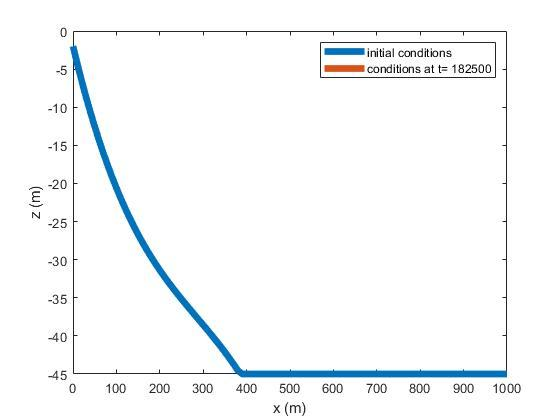

Figure 2. Model run with dx =10, dt = 0.1 days, tf = 500*365 days, S = 0, N = 0

Given the assumption by Bakker of S = 0, our model does not produce any final results. We can attribute this to the fact that S is in the denominator of several coefficients throughout and division by 0 is impossible.

Figure 3 is the original figure from Bakker, where initial conditions are plotted as the left most bold line and final conditions at t = 500 years (500*365 days) are plotted with the dashed line.

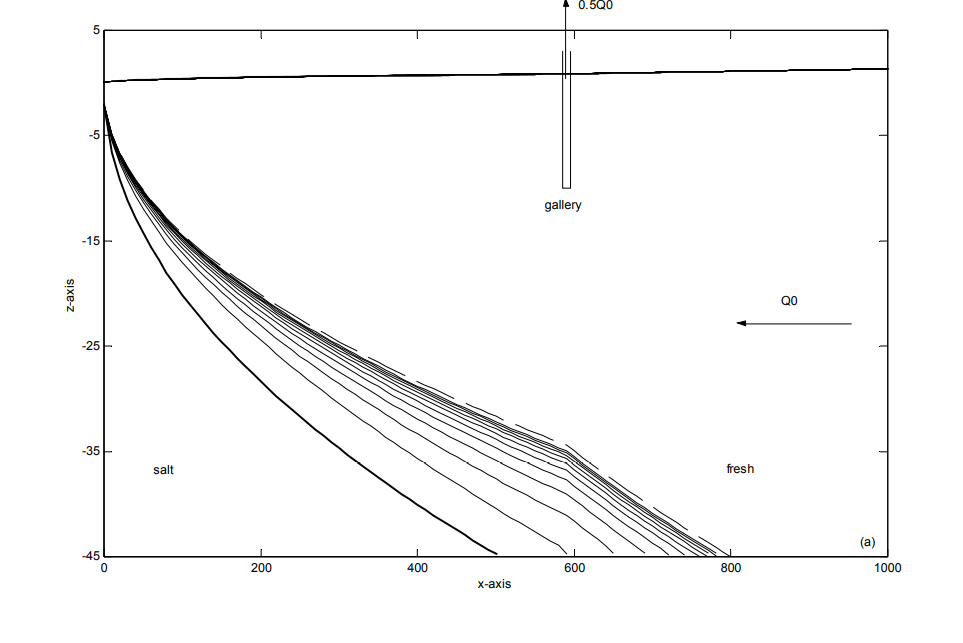

Figure 3. Original Figure 1a from Bakker. 

Comparing Figures 2 and 3, we can confirm that the initial conditions in our model match those of Bakker's.

Figure 4 plots the initial and final conditions at t=500*365 days when S and N are increased to equal 1.

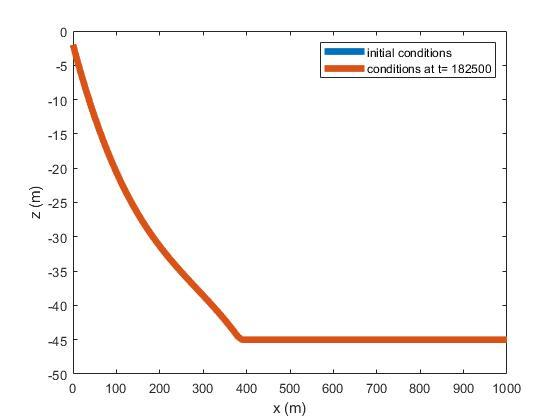

Figure 4. Model run with dx =10, dt = 0.1 days, tf = 500*365 days, S = 1, N = 1

In Figure 4, the final conditions are equivalent to the initial conditions. The model does not force the interface or head with time. 

Reviewing Bakker's given equations and assumptions, it is clear that our model was not running as it should. **Upon closer inspection, we propose that equation 4, the Ghyben-Herzberg condition, should not have a negative sign (as written in Bakker) and should be written instead as (Verruijt, 1968):**

This assumption alters line 106: previously written as h = -zeta/vs, it is now written h = zeta/vs.

**The following figures were generated using the above assumption:**

Figure 5 is produced using the same parameters as figure 4.

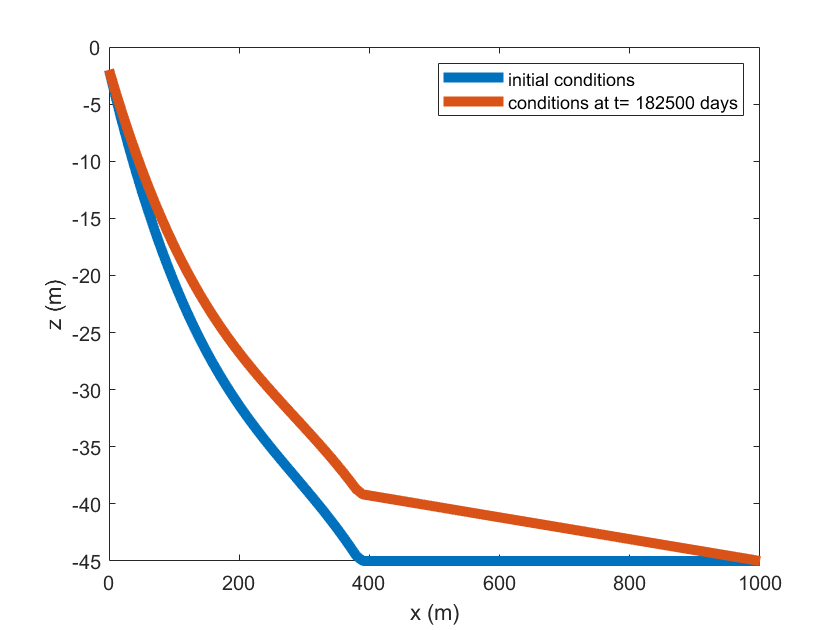

Figure 5. Model run with dx =10, dt = 0.1 days, tf = 500*365 days, S = 1, N = 1

Figure 5 shows the interface rising over time, signifying saltwater intrusion. Comparing figure 5 to figure 3, Bakker's results, the final conditions are relatively similar. Our model depicts saltwater intruding further into the freshwater zone, but at lower depths than Bakker's model.

Figure 6 plots the initial and final interface position at t = 500*365 days when dt is reduced to 0.05 days.

Figure 6. Model run with dx =10, dt = 0.05 days, tf = 500*365 days, S = 1, N = 1

Because we are using the forward Euler method, we would expect that decreasing the timestep dt would produce more accurate results. Comparing figures 5 and 6, however, there are no apparent differences using a relatively smaller timestep. There are, in fact, limitations to how large dt can be. The model does plot a final interface when dt >= approximately 0.5

## Conclusions

Our model simulates the intrusion of saltwater into a freshwater channel under a very specific set of conditions. The plots generated provide a visual as to how the interface between fresh- and salt-water bodies progresses over time. Because salt water is more dense than fresh water, the salt water will sink and force freshwater upwards and to flow out as saltwater intrudes.

Given the highly specific set of parameters for this model, there are many improvements that could be made to make it more accurate and applicable to real world environments. The model we are using assumes the presence of a sharp interface between freshwater and seawater with no mixing. More accurate models account for vertical velocities to model the gradient transition zone from saltwater to freshwater. (Putti & Paniconi, 1995). Other models also differentiate between saltwater intrusion into confined and unconfined aquifers (Jazar, 2014).

## References

- Bakker, M. (2000). Simple groundwater flow models for seawater intrusion, Proceedings of SWIM16, Wolin Island, Poland (2000): 180-182.

- Bakker, M., Schaars, F., Hughes, J.D., Langevin, C.D., and Dausman, A.M. (2013). Documentation of the seawater intrusion (SWI2) package for MODFLOW. *U.S. Geological Survey Techniques and Methods, book 6, chap. A46, 47 p.,* [http://pubs.usgs.gov/tm/6a46/](http://pubs.usgs.gov/tm/6a46/).

- Barlow, P.M., Reichard, E.G. (2010). Saltwater intrusion in coastal regions of North America. *Hydrogeol J* 18, 247–260 [https://doi.org/10.1007/s10040-009-0514-3](https://doi.org/10.1007/s10040-009-0514-3)

- Bouzouf, B., Ouazar, D., Himi, M., Cas, A.(n.d.) Salt water Modeling and Simulation of Llobregat Delta Aquifer. *Proceedings of the 16th Salt Water Intrusion Meeting, Wolin Island, Poland, 2000. *http://www.swim-site.nl/pdf/swim16/bouzouf.pdf

- Jazar, M., Monneau, R. (2014). Derivation of seawater intrusion models by fromal asymptotics*.* *SIAM Journal on Applied Mathematics*, *74*(4), 1152–1173, (2014). [http://www.jstor.org/stable/24511104](http://www.jstor.org/stable/24511104) 

- Putti, M. & Paniconi, C. (1995). Picard and Newton linearization for the coupled model for saltwater intrusion in aquifers, *Advances in Water Resources,* 18 (3), 159-170. [https://doi.org/10.1016/0309-1708(95)00006-5](https://doi.org/10.1016/0309-1708(95)00006-5)

- USDA. (2019). Saltwater Intrusion: A Growing Threat to Coastal Agriculture. https://www.climatehubs.usda.gov/hubs/northeast/topic/saltwater-intrusion-growing-threat-coastal-agriculture  

- USGS. (n.d.) Sea Level Rise and the Marshall Islands. [https://www.usgs.gov/mission-areas/water-resources/science/saltwater-intrusion?qt-science_center_objects=0#qt-science_center_objects](https://www.usgs.gov/mission-areas/water-resources/science/saltwater-intrusion?qt-science_center_objects=0#qt-science_center_objects)

- Verruijt, A. (1968). A NOTE ON THE GHYBEN-HERZBERG FORMULA, Hydrological Sciences Journal, 13:4, 43-46, DOI: 10.1080/02626666809493624